clear all
clf

s1 = readtable ('GeographicUK.xlsx'); % reading data from the specific Data File

s2 = readtable ('Greenland.xlsx');

s3 = readtable ('Spain.xlsx');

s4 = readtable ('Netherlands.xlsx');

s5 = readtable ('Norway.xlsx');

s6 = readtable ('Syria.xlsx');


t1 = readtable('UK_AAT.xls');
t2 = readtable('Greenland_AAT.xls');
t3 = readtable('Spain_AAT.xls');
t4 = readtable('Netherlands_AAT.xls');
t5 = readtable('Norway_AAT.xls');
t6 = readtable('Syria_AAT.xls');

%means and medians of H2, H3, O18 and temperature for different locations
means=[mean(s1.H2,'omitnan'), mean(s1.H3,'omitnan'), mean(s1.O18,'omitnan'), mean(t1.tas,'omitnan')];
medians=[median(s1.H2,'omitnan'), median(s1.H3,'omitnan'), median(s1.O18,'omitnan'), median(t1.tas,'omitnan')];

means=[means;mean(s2.H2,'omitnan'), mean(s2.H3,'omitnan'), mean(s2.O18,'omitnan'), mean(t2.tas,'omitnan')];
medians=[medians;median(s2.H2,'omitnan'), median(s2.H3,'omitnan'), median(s2.O18,'omitnan'), median(t2.tas,'omitnan')];

means=[means;mean(s3.H2,'omitnan'), mean(s3.H3,'omitnan'), mean(s3.O18,'omitnan'), mean(t3.tas,'omitnan')];
medians=[medians;median(s3.H2,'omitnan'), median(s3.H3,'omitnan'), median(s3.O18,'omitnan'), median(t3.tas,'omitnan')];

means=[means;mean(s4.H2,'omitnan'), mean(s4.H3,'omitnan'), mean(s4.O18,'omitnan'), mean(t4.tas,'omitnan')];
medians=[medians;median(s4.H2,'omitnan'), median(s4.H3,'omitnan'), median(s4.O18,'omitnan'), median(t4.tas,'omitnan')];

means=[means;mean(s5.H2,'omitnan'), mean(s5.H3,'omitnan'), mean(s5.O18,'omitnan'), mean(t5.tas,'omitnan')];
medians=[medians;median(s5.H2,'omitnan'), median(s5.H3,'omitnan'), median(s5.O18,'omitnan'), median(t5.tas,'omitnan')];

means=[means;mean(s6.H2,'omitnan'), mean(s6.H3,'omitnan'), mean(s6.O18,'omitnan'), mean(t6.tas,'omitnan')];
medians=[medians;median(s6.H2,'omitnan'), median(s6.H3,'omitnan'), median(s6.O18,'omitnan'), median(t6.tas,'omitnan')];



According to the  reference *G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017 *on page 3707, the abundance of deuterium is measured with the following formula:


$$\delta D=\left(\frac{R_{\mathrm{sample}} }{R_{\mathrm{VSMOW}} }-1\right)\cdot 1000\text{ }‰$$


where:

$R_{\mathrm{sample}}$ is the ratio of deuterium to the common, stable isotope of hydrogen in the samples considered,

 $R_{\mathrm{VSMOW}}$ is the same ratio but for a reference sample with the isotopic composition of the Vienna standard mean ocean water.


$$R_{\text{VSMOW}} =155\ldotp 76\pm 0\ldotp 1ppm$$
 


% The H3 abundance is not given in Delta D, but in TU (Tritium atoms per 1018 Hydrogen atoms), so Delta D must be calculated:
vsmow=1.85*10^-11;   %Given in ppm 
means(:,2)=((means(:,2).*(1/1018)./vsmow)-1).*1000

means =    1.0e+13 *

   -0.0000    1.6927   -0.0000    0.0000
   -0.0000    3.1077   -0.0000   -0.0000
   -0.0000    0.0442   -0.0000    0.0000
   -0.0000    0.1662   -0.0000    0.0000
   -0.0000    2.0974   -0.0000    0.0000
   -0.0000    0.0387   -0.0000    0.0000


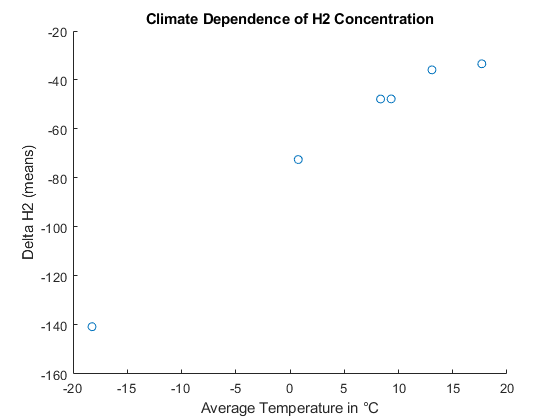

medians(:,2)=((medians(:,2).*(1/1018)./vsmow)-1).*1000;


%Plot scatterplots of isotope concentration in precipitation vs temperature

scatter(means(:,4),means(:,1));     %H2 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Climate Dependence of H2 Concentration');

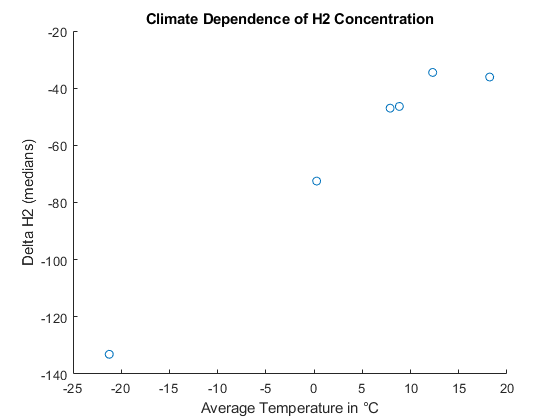


scatter(medians(:,4),medians(:,1));     %H2 median values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

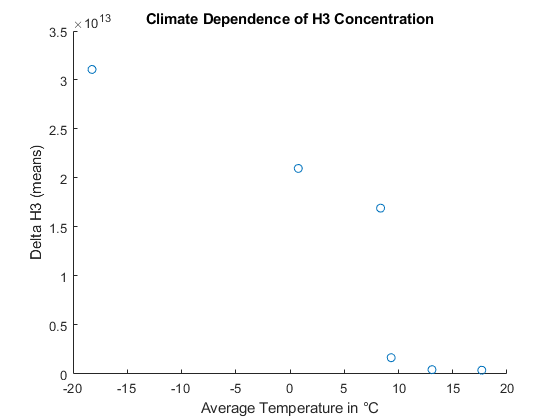


scatter(means(:,4),means(:,2));     %H3 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (means)');
title('Climate Dependence of H3 Concentration');

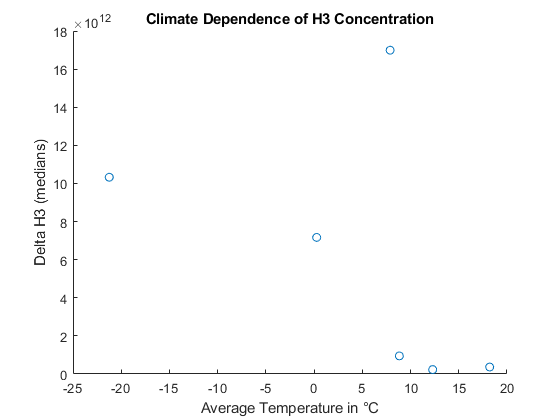


scatter(medians(:,4),medians(:,2));     %H3 median values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Climate Dependence of H3 Concentration');

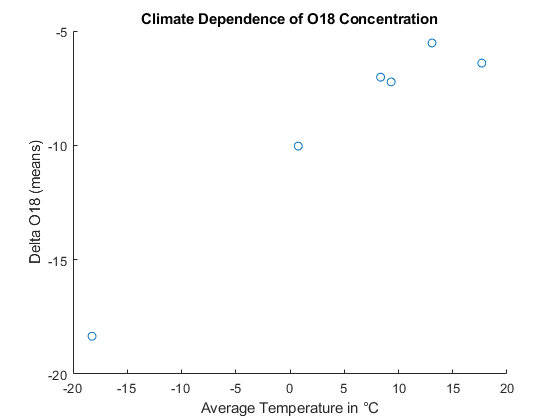


scatter(means(:,4),means(:,3));     %O18 mean values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Climate Dependence of O18 Concentration');

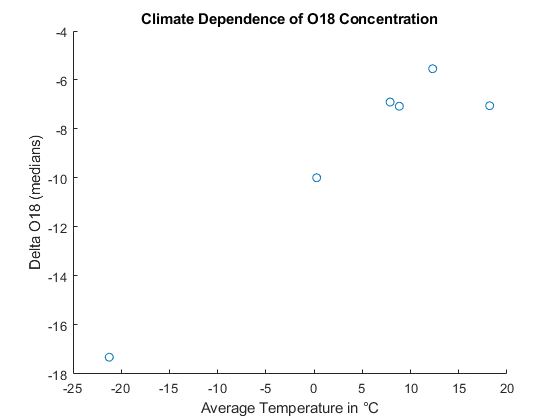


scatter(medians(:,4),medians(:,3));     %O18 median values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (medians)');
title('Climate Dependence of O18 Concentration');